# SVPWM

r=linspace(0, 2*pi, 256);
d=linspace(0, 360, 256);
SPWM = [cos(r);cos(r-pi*2/3);cos(r+pi*2/3)]';

lim_up = max(-1-SPWM')';
lim_down = min(1-SPWM')';
opt_up  = max(-sqrt(3)/2-SPWM')';
opt_down = min(sqrt(3)/2-SPWM')';
opt = min(abs(opt_up),abs(opt_down)).*sign(opt_up);
mid_s = median(SPWM')/2;
sin_s = -cos(r'*3)/6;

## 信号分析

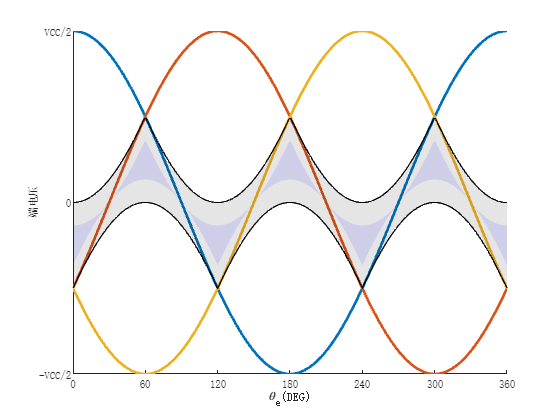

figure(1);
hold on;

plot(d,SPWM,'linewidth', 2);
plot(d,[lim_up,lim_down],'k');

fill_x = [d, fliplr(d)];
fill_y = [lim_down', fliplr(lim_up')];
fill(fill_x, fill_y, 'k', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

fill_x = [d, fliplr(d)];
fill_y = [opt_down', fliplr(opt_up')];
fill(fill_x, fill_y, 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

set(gca, 'FontSize', 8,'FontName', '宋体');
xlabel('\theta_e(DEG)','Interpreter', 'tex', 'FontSize', 8);
xlim([0,360]);
xticks(0:60:360); % 设置刻度

xticks(0:60:360); % 设置刻度
ylabel('端电压', 'FontSize', 8);
ylim([-1,1]);
yticks(-1:1:1); % 设置刻度
yticklabels({'-VCC/2', '0', 'VCC/2'});
hold off;

## SVPWM

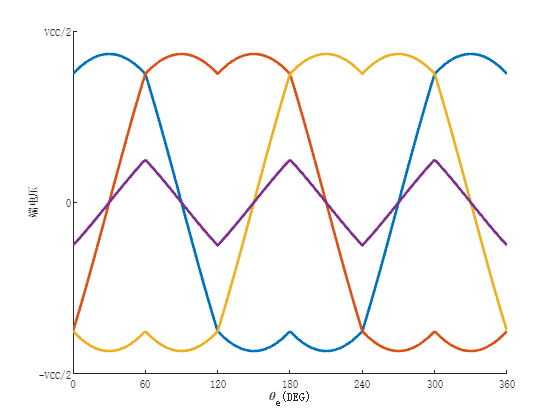

figure(2);
plot(d,[SPWM+mid_s',mid_s'],'linewidth', 2);
set(gca, 'FontSize', 8,'FontName', '宋体');
xlabel('\theta_e(DEG)','Interpreter', 'tex', 'FontSize', 8);
xlim([0,360]);
xticks(0:60:360); % 设置刻度

xticks(0:60:360); % 设置刻度
ylabel('端电压', 'FontSize', 8);
ylim([-1,1]);
yticks(-1:1:1); % 设置刻度
yticklabels({'-VCC/2', '0', 'VCC/2'});
box off;

## 正弦注入

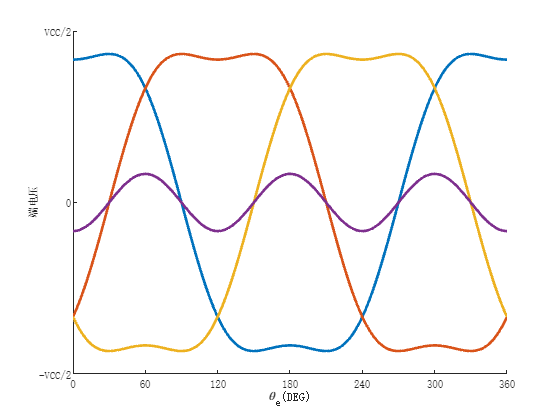

figure(3);
plot(d,[SPWM+sin_s,sin_s],'linewidth', 2);
set(gca, 'FontSize', 8,'FontName', '宋体');
xlabel('\theta_e(DEG)','Interpreter', 'tex', 'FontSize', 8);
xlim([0,360]);
xticks(0:60:360); % 设置刻度

xticks(0:60:360); % 设置刻度
ylabel('端电压', 'FontSize', 8);
ylim([-1,1]);
yticks(-1:1:1); % 设置刻度
yticklabels({'-VCC/2', '0', 'VCC/2'});
box off;

## 极限注入

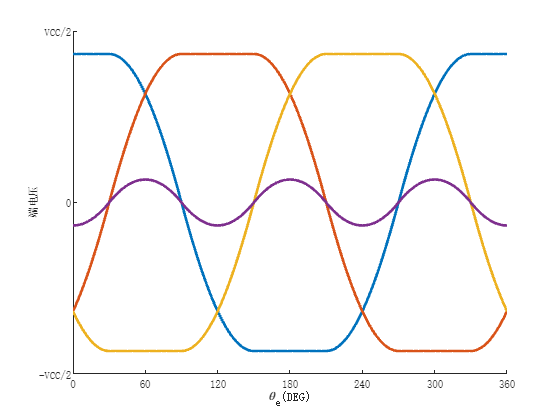

figure(4);
plot(d,[SPWM+opt,opt],'linewidth', 2);
set(gca, 'FontSize', 8,'FontName', '宋体');
xlabel('\theta_e(DEG)','Interpreter', 'tex', 'FontSize', 8);
xlim([0,360]);
xticks(0:60:360); % 设置刻度

xticks(0:60:360); % 设置刻度
ylabel('端电压', 'FontSize', 8);
ylim([-1,1]);
yticks(-1:1:1); % 设置刻度
yticklabels({'-VCC/2', '0', 'VCC/2'});
box off;